# **Carga y desarrollo de un Robot Manipulador Móvil. Además de planificación y ejecución de trayectorias en el Espacio Cartesiano. **

Este ejemplo muestra generar un Robot Manipulador Móvil para una simulación de trayectoria articular interpolada para mover el Efector Final desde una pose incial de reposo a otra deseada.

Carga del Robot Manipulador Móvil como un modelo basado en un "Rigid Body Tree" (RBT).

Modelos de Robots Manipuladores disponibles:

**1 - "abbIrb120"     2 - "abbIrb120T"        3 - "abbIrb1600"        4 - "fanucLRMate200ib"        5 - "fanucM16ib"        **

**6 - "universalUR3"        7 - "universalUR3e"        8 - "universalUR5"        9 - "universalUR5e"        **

**10 - "universalUR10"        11 - "universalUR10e"        12 - "universalUR16e" **       

Modelos de Robots Móviles:

**1 -"clearpathHusky"**

Estos Robots son los que están guardados en la librería de MATLAB (MathWorks).

% Se mostrará en pantalla un pequeño programa donde preguntará que robot se
% ha elegido, según su número. Además hay que decir si la plataforma
% escogida para el estudio es de tracción diferencial o no. Si la respuesta
% es afirmativa hay que escribir un 1 y si es negativa un 0.

MNum = input('El número del Robot Manipulador es: ');
PNum = input('El número de la Plataforma Móvil es: ');
TDiferencial = input('¿ Es de tracción diferencial ? : ');

% Según el número escogido se guardará en la variable MNum el nombre del
% Robot Manipulador elegido.
% Además se guarda en la variable de configuración actual, el valor de las
% articulaciones en la posición HOME.
switch MNum
    case 1
        MNOM = "abbIrb120";
        disp('El Robot Manipulador elegido es: abbIrb120')
        currentRobotJConfig = [0 0 0 0 0 0 0 0 0 0 0 0];

    case 2
        MNOM = "abbIrb120T"
        disp('El Robot Manipulador elegido es: abbIrb120T')
        currentRobotJConfig = [0 0 0 0 0 0 0 0 0 0 0 0];

    case 3
        MNOM = "abbIrb1600" 
        disp('El Robot Manipulador elegido es: abbIrb1600')
        currentRobotJConfig = [0 0 0 0 0 0 0 0 0 0 0 0];

    case 4
        MNOM = "fanucLRMate200ib" 
        disp('El Robot Manipulador elegido es: fanucLRMate200ib')
        currentRobotJConfig = [0 0 0 0 0 0 0 0 0 0 0 0];

    case 5
        MNOM = "fanucM16ib" 
        disp('El Robot Manipulador elegido es: fanucM16ib')
        currentRobotJConfig = [0 0 0 0 0 0 0 0 0 0 0 0];

    case 6
        MNOM = "universalUR3" 
            disp('El Robot Manipulador elegido es: universalUR3')
        currentRobotJConfig = [0 0 0 0 0 0 0 -1.5708 0 -1.5708 0 0];

    case 7
        MNOM = "universalUR3e"
        disp('El Robot Manipulador elegido es: universalUR3e')
        currentRobotJConfig = [0 0 0 0 0 0 0 -1.5708 0 -1.5708 0 0];

    case 8
        MNOM = "universalUR5"
        disp('El Robot Manipulador elegido es: universalUR5')
        currentRobotJConfig = [0 0 0 0 0 0 0 -1.5708 0 -1.5708 0 0];

    case 9
        MNOM = "universalUR5e"
        disp('El Robot Manipulador elegido es: universalUR5e')
        currentRobotJConfig = [0 0 0 0 0 0 0 -1.5708 0 -1.5708 0 0];

    case 10
        MNOM = "universalUR10"
        disp('El Robot Manipulador elegido es: universalUR10')
        currentRobotJConfig = [0 0 0 0 0 0 0 -1.5708 0 -1.5708 0 0];
        
    case 11
        MNOM = "universalUR10e"
        disp('El Robot Manipulador elegido es: universalUR10e')
        currentRobotJConfig = [0 0 0 0 0 0 0 -1.5708 0 -1.5708 0 0];

    case 12
        MNOM = "universalUR16e"
        disp('El Robot Manipulador elegido es: universalUR16e')
        currentRobotJConfig = [0 0 0 0 0 0 0 -1.5708 0 -1.5708 0 0];
       
end

MNOM = "universalUR5"

El Robot Manipulador elegido es: universalUR5



% Según el número escogido se guardará en la variable MNum el nombre del
% Robot Manipulador elegido.

switch PNum
    case 1
        PNOM = "clearpathHusky"
        disp('El Robot Móvil elegido es: clearpathHusky')
        top_plate = 'top_plate_link'
end                                                                               %     case 2

PNOM = "clearpathHusky"

El Robot Móvil elegido es: clearpathHusky


top_plate = 'top_plate_link'

                                                                                %         PNOM = "clearpathHusky"
                                                                                %         disp('El Robot Móvil elegido es: clearpathHusky')
                                                                                %         top_plate = 'top_plate_link'


% A través del comando loadrobot, se carga el urdf del robot con el nombre
% escogido

manipulador = loadrobot(MNOM,'DataFormat','row','Gravity',[0 0 -9.81]);  % En la variable "manipulador" se guarda el robot elegido en formato .urdf.
plataforma = loadrobot(PNOM, DataFormat='row');                          % En la variable "plataforma" se guarda el robot elegido en formato .urdf.

% Para que no haya problemas con los dobles nombres de la base, se cambia
% el nombre de la base de la plataforma Móvil.

plataforma.BaseName = 'base_link1';

                                                                        % b1 = rigidBody('b1');
                                                                        % 
                                                                        % replaceBody(UR5,'base_link',b1);

% A través del comando adsubtree se une el Robot Manipulador a la
% Plataforma Móvil

addSubtree(plataforma,top_plate,manipulador,ReplaceBase=false); 

% Según si se ha escogido una plataforma móvil con tracción diferencial o
% no se tendrá una articulación prismática extra en la "Base Flotante"

if TDiferencial == 1
    N = 2;
else
    N = 1;
end

% Para que la Plataforma Móvil se pueda mover con tracción diferencial, hay que crear una "Base
% Flotante" para ello se va a crear un subrobot (RBT) con dos grados de
% libertad, es decir, creando primero una articulación prismática en el eje X y después
% una de revolución en el eje Z.

% Se crea el robot en formato (RBT)
robot = rigidBodyTree();
robot.BaseName = 'world1';                                                                          % Se expecifica cual va a ser la base
robot.DataFormat = 'row';                                                                           % Se expecifica el formato de los valores del robot.
jointAxisName = {'X', 'Y', 'Z'};                                                                    % Nombre de los ejes que se van a usar
jointAxisValue = eye(3);                                                                            % Se asigna cual va a ser el valor de cada eje 
parentBodyName = robot.BaseName;                                                                    % Se inicializa el primer parentBody, donde se va a unir el primer cuerpo del subrobot.

% Creación de la articulación prismática
for i = 1:numel(jointAxisName)-N                                                                    % Según si es Tracciónb Diferencial o no
    bodyName = ['base' jointAxisName{i} 'TransBody'];                                               % Se crean los nombres de los cuerpos prismáticos del robot
    jointName = ['base' jointAxisName{i} 'TransJoint'];                                             % Se crean los nombres de las articulaciones prismáticos del robot
    rb = rigidBody(bodyName);                                                                       % Se añade el cuerpo al subrobot
    rbJoint = rigidBodyJoint(jointName, 'prismatic');                                               % Se crea la articulación
    rbJoint.JointAxis = jointAxisValue(i,:);                                                        % Se especifica el eje de la articulación
    rbJoint.PositionLimits = [-inf inf];                                                            % Los límites de movimiento de la articulación prismática
    rb.Joint = rbJoint;                                                                             % Se añade la articulación al cuerpo rígido                                                   
    
    % Se añade el cuerpo rígido al robot usando el parentBody especificado
    robot.addBody(rb, parentBodyName);
    parentBodyName = rb.Name; % Se actualiza el parentBody
end

% Creación de la articulación de revolución
for i = 3:numel(jointAxisName)
    bodyName = ['base' jointAxisName{i} 'RevBody'];
    jointName = ['base' jointAxisName{i} 'RevJoint'];
    rb = rigidBody(bodyName);
    rbJoint = rigidBodyJoint(jointName, 'revolute');
    rbJoint.JointAxis = jointAxisValue(i,:);
    rbJoint.PositionLimits = [-inf inf];
    rb.Joint = rbJoint;
    
    % Añadir al robot usuando el cuerpo previo como "parent" 
    robot.addBody(rb, parentBodyName);
    parentBodyName = rb.Name; % Actualizar el nombre del cuerpo del "parent"
end

% se añade la "Base Flotante" al subconjunto de Manipulador Móvil, el
% resultado es el robot final.
addSubtree(robot,'baseZRevBody',plataforma,ReplaceBase=false);

Se obtiene el número de articulaciones y el marco de RBT del Efector Final.

numJoints = numel(currentRobotJConfig);
endEffector = 'tool0';

Se especifica el paso de tiempo de trayectoria y la velocidad de herramienta deseada aproximada.

timeStep = 0.1; % segundos
toolSpeed = 0.1; % m/s

Se inicializa la pose inicial y final del Efector Final.

jointInit = currentRobotJConfig;
taskInit = getTransform(robot,jointInit,endEffector);
taskFinal = trvec2tform([2,0.8,0.3])*axang2tform([0 0 1 pi/2]);  % Esta linea de código es la que modificará para hacer una trayectoria u otra

## Genera una trayectoria en el Espacio Cartesiano

Calcula la trayectoria Cartesiana y los puntos intermedios por medio de interpolación.

El primer paso es calcular la distancia que tiene que moverse la herramienta.

distance = norm(tform2trvec(taskInit)-tform2trvec(taskFinal));

Se define los tiempos de movimiento en función de la distancia que se tiene que recorrer y la velocidad deseada de la herramienta.

initTime = 0;
finalTime = (distance/toolSpeed) - initTime;
trajTimes = initTime:timeStep:finalTime;
timeInterval = [trajTimes(1); trajTimes(end)];

Se interpola entre las poses *taskInicial* y *taskFinal *para obtener los valores de los puntos intermedios de la trayectoria.

[taskWaypoints,taskVelocities] = transformtraj(taskInit,taskFinal,timeInterval,trajTimes); 

## Control de Movimiento en el Espacio Cartesiano

Crea un modelo de movimiento en el Espacio Cartesiano basandose en el control de las articulaciones a través de un PD. El objeto `taskSpaceMotionModel` modela el movimiento del modelo Rigid Body Tree bajo un control proporcional-derivativo.

tsMotionModel = taskSpaceMotionModel('RigidBodyTree',robot,'EndEffectorName','tool0');

Se especifica la ganancia proporcional y derivativa.

% Si se dejan a cero, el comportamiento de las articulaciones se basa en
% las posicines de referencia.
tsMotionModel.Kp(1:3,1:3) = 0;
tsMotionModel.Kd(1:3,1:3) = 0;

Se define los estados iniciales (posiciones de las articulaciones y velocidades).

q0 = currentRobotJConfig; 
qd0 = zeros(size(q0));

Para resolver el problema de simulación de movimiento del robot, se utliza el ODE15. Dado que el estado de referencia cambia en cada instante, se requiere una función contenedora para actualizar la entrada de trayectoria interpolada a la derivada de estado en cada instante. Por lo tanto, se pasa una función auxiliar de ejemplo como identificador de función al solucionador de ODE. Los estados del manipulador resultantes se generan en stateTask.

[tTask,stateTask] = ode15s(@(t,state) exampleHelperTimeBasedTaskInputs(tsMotionModel,timeInterval,taskInit,taskFinal,t,state),timeInterval,[q0; qd0]);

## Generación de la trayectoria en el Espacio Articular

Se genera la Cinemática Inversa del Robot.

% ik = inverseKinematics('RigidBodyTree',robot);          % Para ello se usa el objeto de MATLAB, llamado inverseKinematics, donde se especifica a que robot se hace referencia
% ik.SolverParameters.AllowRandomRestart = false;
% weights = [1 1 1 1 1 1];

Se calcula las configuraciones articulares iniciales y deseadas usando la Cinemática Inversa. Se ajustan los valores a pi.

% initialGuess = jointInit;
% jointFinal = ik(endEffector,taskFinal,weights,initialGuess);

Por defecto, la solución IK respeta los límites de las juntas. Sin embargo, para juntas continuas (juntas giratorias con rango infinito), los valores resultantes pueden ser innecesariamente grandes y pueden ajustarse a [-pi, pi] para garantizar que la trayectoria final cubra una distancia mínima.

% wrappedJointFinal = wrapToPi(jointFinal);

Se interpola utilizando una dunción polinomial cúbica para generar una matriz de configuraciones de articulaciones espaciadas uniformemente. Se usa un B-spline para generar una trayectoria suave.

% ctrlpoints = [jointInit',wrappedJointFinal'];
% jointConfigArray = cubicpolytraj(ctrlpoints,timeInterval,trajTimes);        % Matriz de configuraciones
% jointWaypoints = bsplinepolytraj(jointConfigArray,timeInterval,1);          % Se ghenera una trayectoria suave,

## Control de trayectoria en el Espacio Articular

Crea un modelo de movimiento en el Espacio Articular basandose en el control de las articulaciones a través de un PD. El objeto `jointSpaceMotionModel` modela el movimiento de un Rigid Body Tree y usa un control proporcional-derivativo para seguir las posiciones articulares especificadas.

% jsMotionModel = jointSpaceMotionModel('RigidBodyTree',robot,'MotionType','PDControl');

Se inicializan los estados (posiciones articulares y velocidades).

% q0 = currentRobotJConfig; 
% qd0 = zeros(size(q0));

Use ode15s para simular el movimiento del robot. Una vez más, se utiliza una función auxiliar de ejemplo como la entrada de control de función para el solucionador de ODE para actualizar las entradas de referencia en cada instante de tiempo. Los estados del espacio conjunto se generan en stateJoint.

% [tJoint,stateJoint] = ode15s(@(t,state) exampleHelperTimeBasedJointInputs(jsMotionModel,timeInterval,jointConfigArray,t,state),timeInterval,[q0; qd0]);

## Visualización de las trayectorias del Robot

Se muestra al robot en la configuración inicial del robot.

show(robot,currentRobotJConfig,'PreservePlot',false,'Frames','off');   % Se utiliza el comando "show" para representar el robot en una "figure" de MATLAB
hold on
axis([-1 2.5 -1 1.5 -0.1 1.5]);                                            % Se inicializan las dimensiones del mapa

Se visualiza la trayectoria en el Espacio Cartesiano. Se itera a través de los estados de `stateTask `y se interpola en función de el `timeStep`.

for i=1:length(trajTimes)
%   Tiempo actual 
    tNow= trajTimes(i);
%   Se interpola a través de las posiciones de las articulaciones para conseguir
%   la configuración en el tiempo actual (tNow)
    configNow = interp1(tTask,stateTask(:,1:numJoints),tNow);
    poseNow = getTransform(robot,configNow,endEffector);
    show(robot,configNow,'PreservePlot',false,'Frames','off');
    taskSpaceMarker = plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'b.','MarkerSize',20);
    drawnow;
end

Se visualiza la trayectoria en el Espacio Articular. Se itera a través de los estados de `jointTask `y se interpola en función de el `timeStep`.

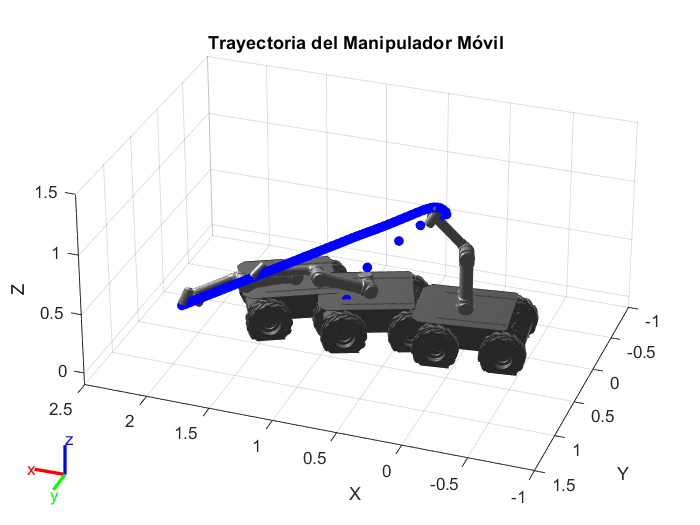

% % Return to initial configuration
%  show(robot,currentRobotJConfig,'PreservePlot',false,'Frames','off');
%  
%  for i=1:length(trajTimes)
%      % Current time 
%      tNow= trajTimes(i);
%      % Interpolate simulated joint positions to get configuration at current time
%      configNow = interp1(tJoint,stateJoint(:,1:numJoints),tNow);
%      poseNow = getTransform(robot,configNow,endEffector);
%      show(robot,configNow,'PreservePlot',false,'Frames','off');
%      jointSpaceMarker = plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'r.','MarkerSize',20);
%      drawnow;
%  end
 
 % Add a legend and title
 %legend([taskSpaceMarker jointSpaceMarker], {'Defined in Task-Space', 'Defined in Joint-Space'});
 title('Trayectoria del Manipulador Móvil')